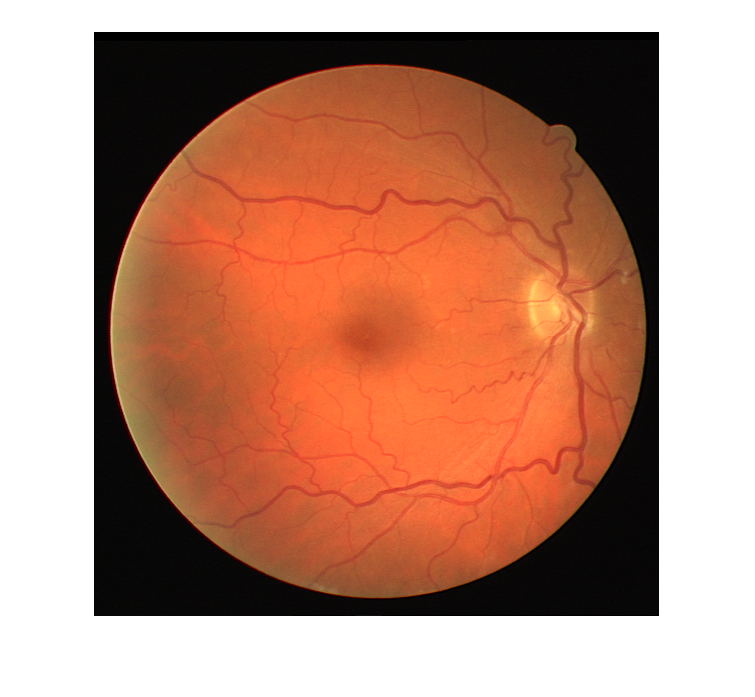

%RGB image
RGB = imread('22_training.tif');
imshow(RGB)

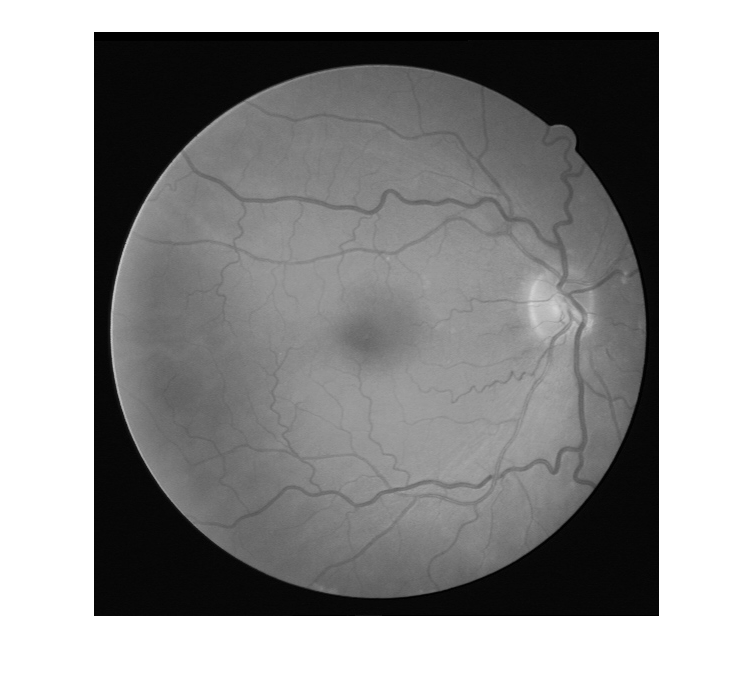

%Grayscale Image
I = 0.33 * RGB(:,:,1) + 0.5 * RGB(:,:,2) + 0.166 * RGB(:,:,3);
figure
imshow(I)

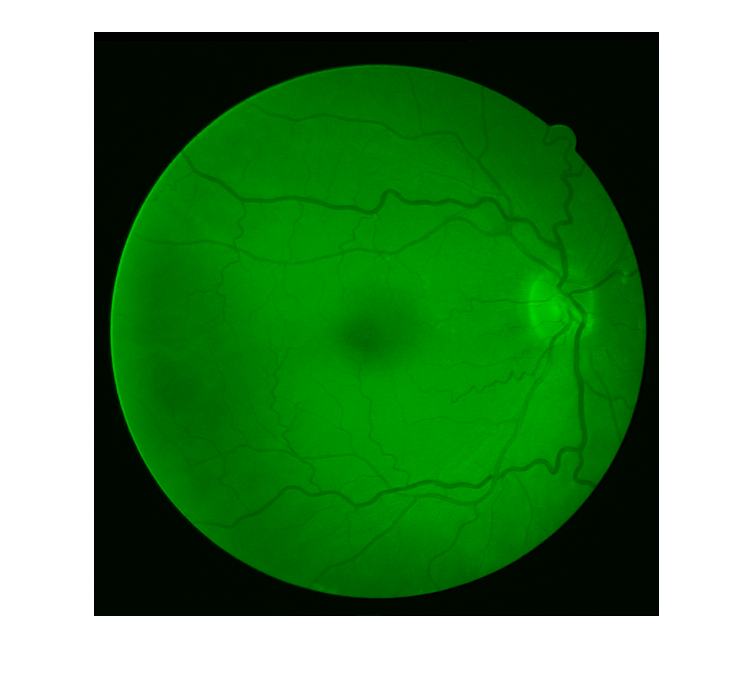

%Green Channel Image
allBlack = zeros(size(I, 1), size(I, 2), 'uint8');
just_green = cat(3, allBlack, I, allBlack);
figure
imshow(just_green)

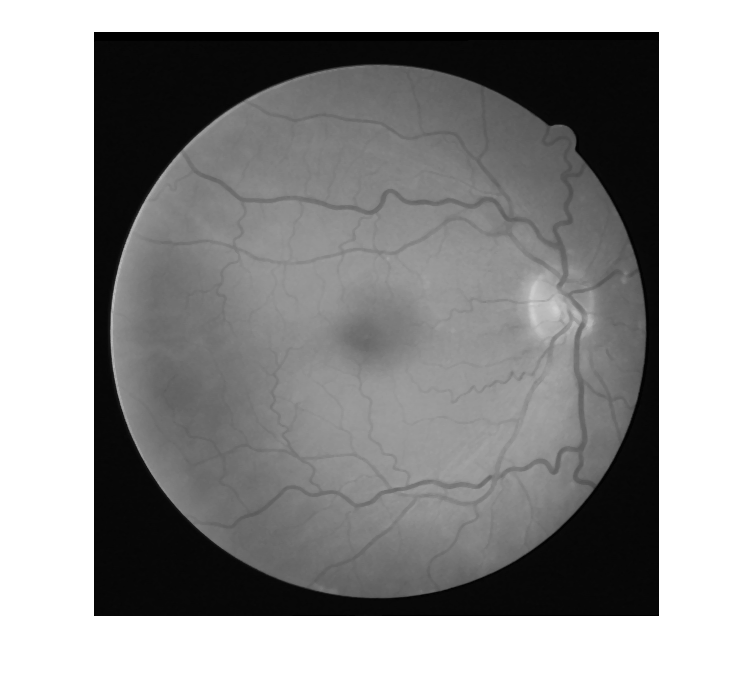

%Median Filter Image
J = medfilt2(I,[3 3]);
figure
imshow(J)

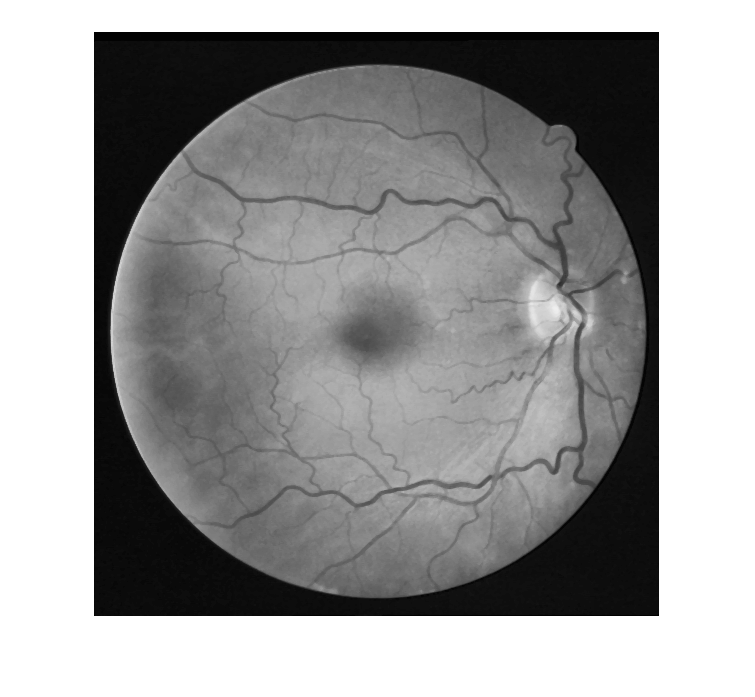

%CLAHE Image
K = adapthisteq(J,'NumTiles', [8,8], 'ClipLimit', 0.005);
figure
imshow(K)

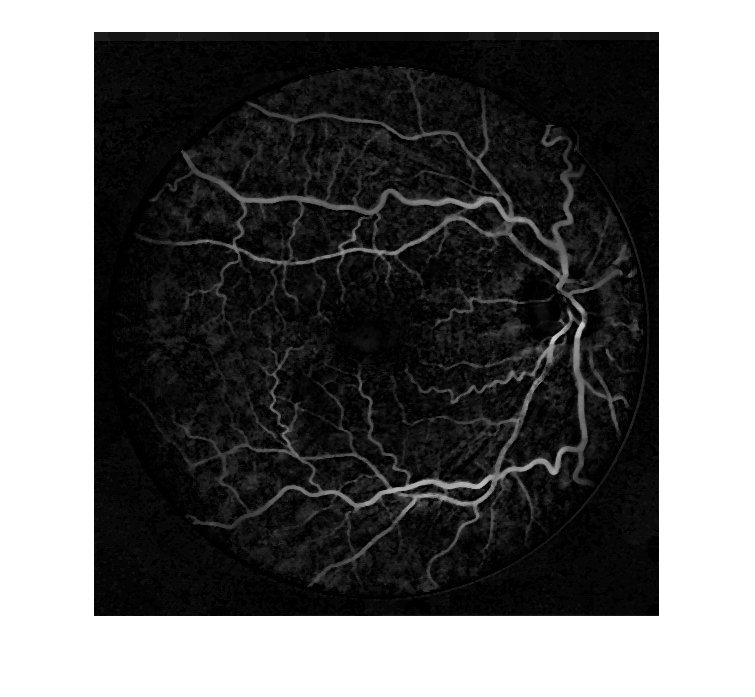

%OD Removal using MM
C = imcomplement(K);
D = adapthisteq(C);
se = strel('disk',10);
E = imopen(D,se);
F = imsubtract(D,E);
figure
imshow(F)

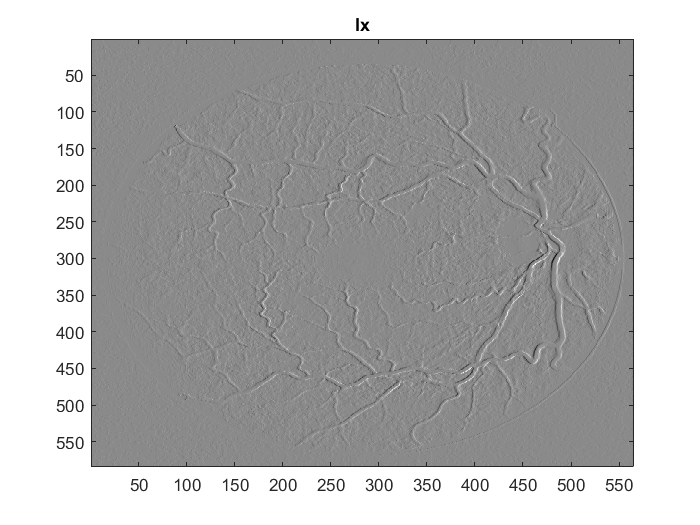

%Image Segmentation using Fuzzy Logic
DP = im2double(F);
Gx = [-1 1];
Gy = Gx';
Ix = conv2(DP,Gx,'same');
figure
image(Ix,'CDataMapping','scaled')
colormap('gray')
title('Ix')

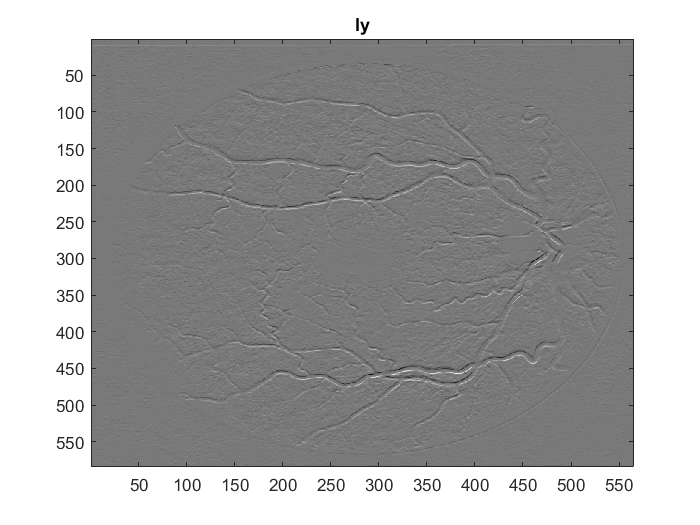

Iy = conv2(DP,Gy,'same');
figure
image(Iy,'CDataMapping','scaled')
colormap('gray')
title('Iy')

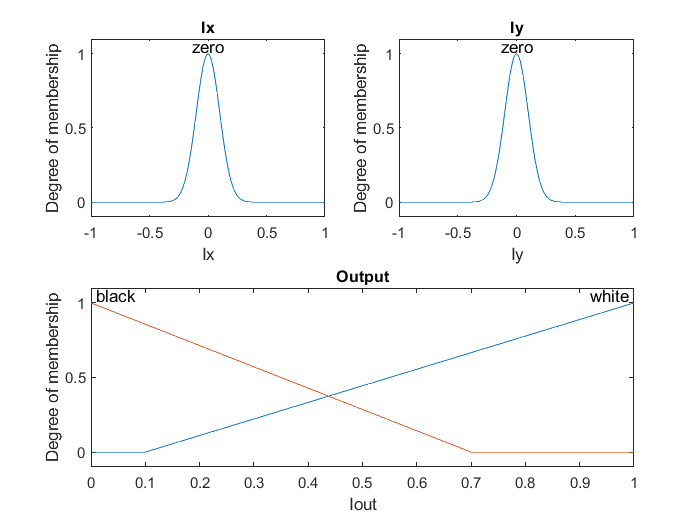


edgeFIS = mamfis('Name','edgeDetection');
%edgeFIS.DefuzzificationMethod = "mom";
edgeFIS = addInput(edgeFIS,[-1 1],'Name','Ix');
edgeFIS = addInput(edgeFIS,[-1 1],'Name','Iy');
sx = 0.1;
sy = 0.1;
edgeFIS = addMF(edgeFIS,'Ix','gaussmf',[sx 0],'Name','zero');
edgeFIS = addMF(edgeFIS,'Iy','gaussmf',[sy 0],'Name','zero');
edgeFIS = addOutput(edgeFIS,[0 1],'Name','Iout');
wa = 0.1;
wb = 1;
wc = 1;
ba = 0;
bb = 0;
bc = 0.7;
edgeFIS = addMF(edgeFIS,'Iout','trimf',[wa wb wc],'Name','white');
edgeFIS = addMF(edgeFIS,'Iout','trimf',[ba bb bc],'Name','black');
figure
subplot(2,2,1)
plotmf(edgeFIS,'input',1)
title('Ix')
subplot(2,2,2)
plotmf(edgeFIS,'input',2)
title('Iy')
subplot(2,2,[3 4])
plotmf(edgeFIS,'output',1)
title('Output')

r1 = "If Ix is zero and Iy is zero then Iout is white";
r2 = "If Ix is not zero or Iy is not zero then Iout is black";
edgeFIS = addRule(edgeFIS,[r1 r2]);
edgeFIS.Rules

ans =   1×2 fisrule array with properties:

    Description
    Antecedent
    Consequent
    Weight
    Connection

  Details:
                       Description              
         _______________________________________

    1    "Ix==zero & Iy==zero => Iout=white (1)"
    2    "Ix~=zero | Iy~=zero => Iout=black (1)"


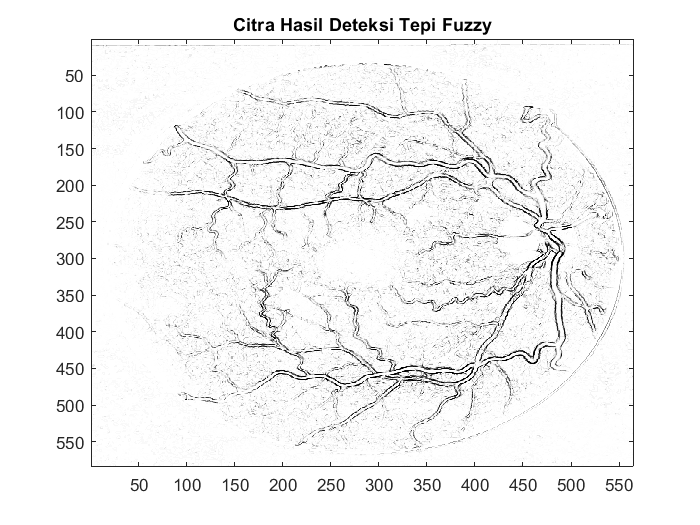

Ieval = zeros(size(DP));
asd = zeros(size(DP));
for ii = 1:size(DP,1)
    Ieval(ii,:) = evalfis(edgeFIS,[(Ix(ii,:));(Iy(ii,:))]');
end
figure
image(Ieval,'CDataMapping','scaled')
colormap('gray')
title('Citra Hasil Deteksi Tepi Fuzzy')

L = logical(mod(Ieval,0.6700));
sample = imread('21_manual1.gif');
samplegold = im2double(sample);
M = logical(samplegold);
similarity = jaccard(L,M)

similarity = 0.0747